close all
clear
clc

% inputs (SI)
jerk = 140;
acceTol = 3;
veloParam = [5000,30000]./60000; % mm/min -> m/s
posParam = [0,-1.4,-3.1,0];
% posMin = 0;
% posMax = -3.2;
% posNo = 3; % No. of reciprocating areas
posRev = -0.1; % position reversal distance
tInt = 0.001;
repeatance = 3;


## 0

t5 = 0:tInt:3;
tList = t5;
posList = zeros(1,length(t5));
veloList = zeros(1,length(t5));
accelList = zeros(1,length(t5));
jerkList = zeros(1,length(t5));

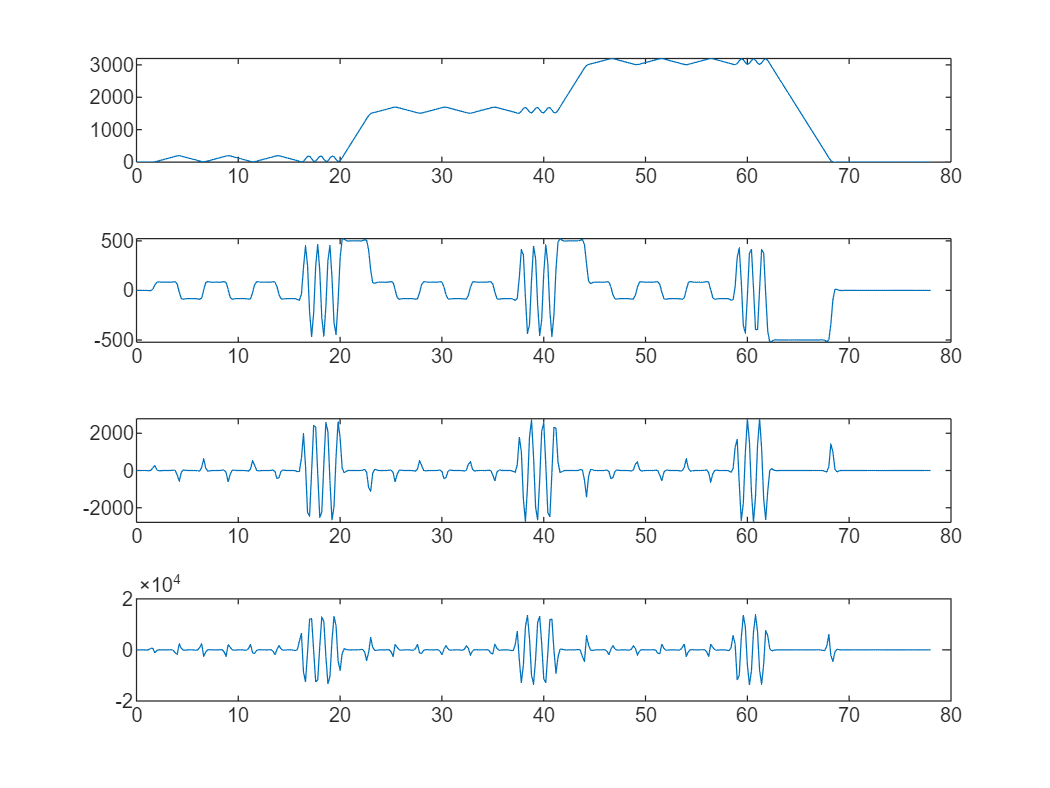

% load('D:\WorkingDir\Experiments\202406-mms-dynamics\Siemens results mat\20240529 Siemens\DYB_A3J140.mat','siemensTable');
% 
% t = siemensTable.time(1:100:end);
% disp = siemensTable.disp1(1:100:end);
% 
% % Q = [t,disp];
% % u = 0:0.0002:1;
% % n = length(disp);
% % uQ = interpParam(Q,"paramMethod","chord");
% % U = nodeVector(3,n,NodeMethod="Interpolation",uQ=uQ);
% % disp1Sp = spapi(U,uQ,Q);
% 
% % dispSp = spapi(3,t,disp);
% dispSp = csaps(t,disp);
% dispInterp = fnval(dispSp,t);
% 
% veloSp = fnder(dispSp,1);
% veloInterp = fnval(veloSp,t);
% 
% accelSp = fnder(dispSp,2);
% accelInterp = fnval(accelSp,t);
% 
% jerkSp = fnder(dispSp,3);
% jerkInterp = fnval(jerkSp,t);
% 
% figure; tiledlayout(4,1); nexttile; plot(t,dispInterp);
% nexttile; plot(t,veloInterp);
% nexttile; plot(t,accelInterp);
% nexttile; plot(t,jerkInterp);